clc; clear; close all; 
addpath('../functions/');
n=200;
t=1;
[ x, z, a, Noise ] = randomAcceleration( n, 0.2, 20, 5, 1, t); 


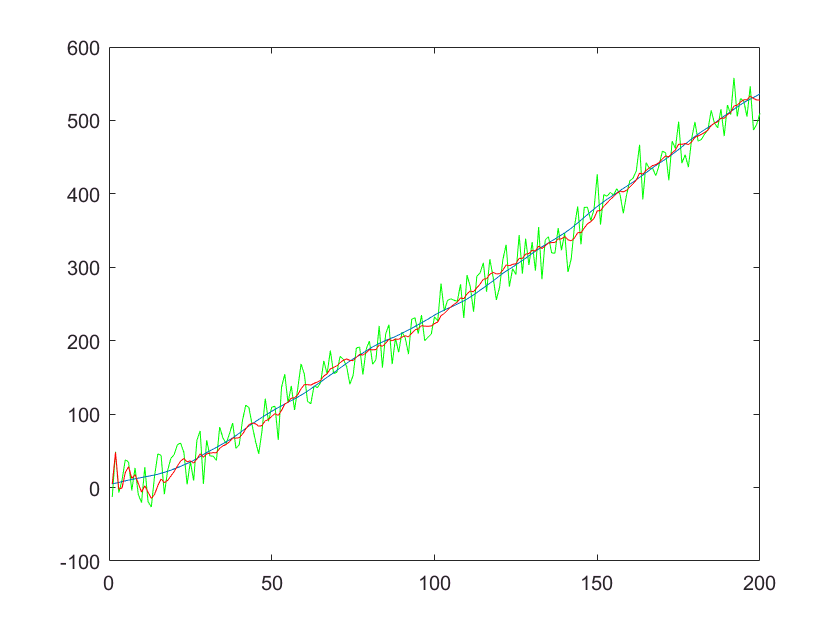

G = [(t^2)/2; t];
F = [ 1, t; 0, 1 ];
H = [1, 0];

X = zeros(2, n);
Z = zeros(1, n);
X(:, 1) = [5; 1];

for i=2:n
    X(:, i) = F*X(:,i-1) + G*a(i);
    Z(i) = H*X(:,i) + Noise(i); 
end

Xk = zeros(2, n);
Xk(:, 1) = [5; 1];

Q=0.04*(G*G');
P=[10000, 0; 0, 10000];

for i=2:n
    P=F*P*F'+Q;
    K=P*H'/(H*P*H'+ 400);
    Xk(:,i) = F*Xk(:, i-1);
    Xk(:,i) = Xk(:,i)+K*(Z(i)-H*Xk(:,i));
    
    P=(eye(2)-K*H)*P;
end

% figure;
plot (z,'green')
hold on;
plot (X(1,:));
plot (Xk(1,:),'red');